# Train a deep learning LSTM network for sequence-to-label classification

[https://in.mathworks.com/help/deeplearning/ref/trainnetwork.html](https://in.mathworks.com/help/deeplearning/ref/trainnetwork.html)

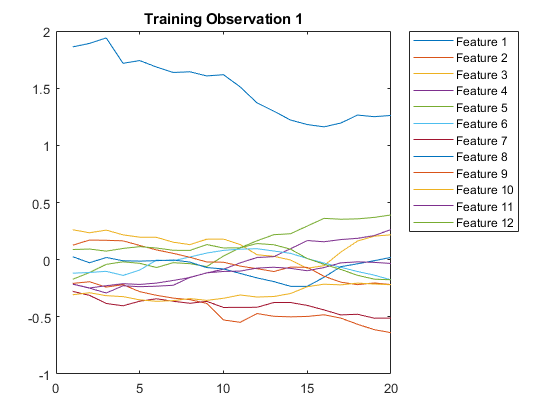

[XTrain,YTrain] = japaneseVowelsTrainData;
figure
plot(XTrain{1}')
title("Training Observation 1")
numFeatures = size(XTrain{1},1);
legend("Feature " + string(1:numFeatures),'Location','northeastoutside')

Define Architecture

inputSize = 12;
numHiddenUnits = 100;
numClasses = 9;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   5x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 12 dimensions
     2   ''   LSTM                    LSTM with 100 hidden units
     3   ''   Fully Connected         9 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex


maxEpochs = 100;
miniBatchSize = 27;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'GradientThreshold',1, ...
    'Verbose',false, ...
    'Plots','training-progress');


Train Network

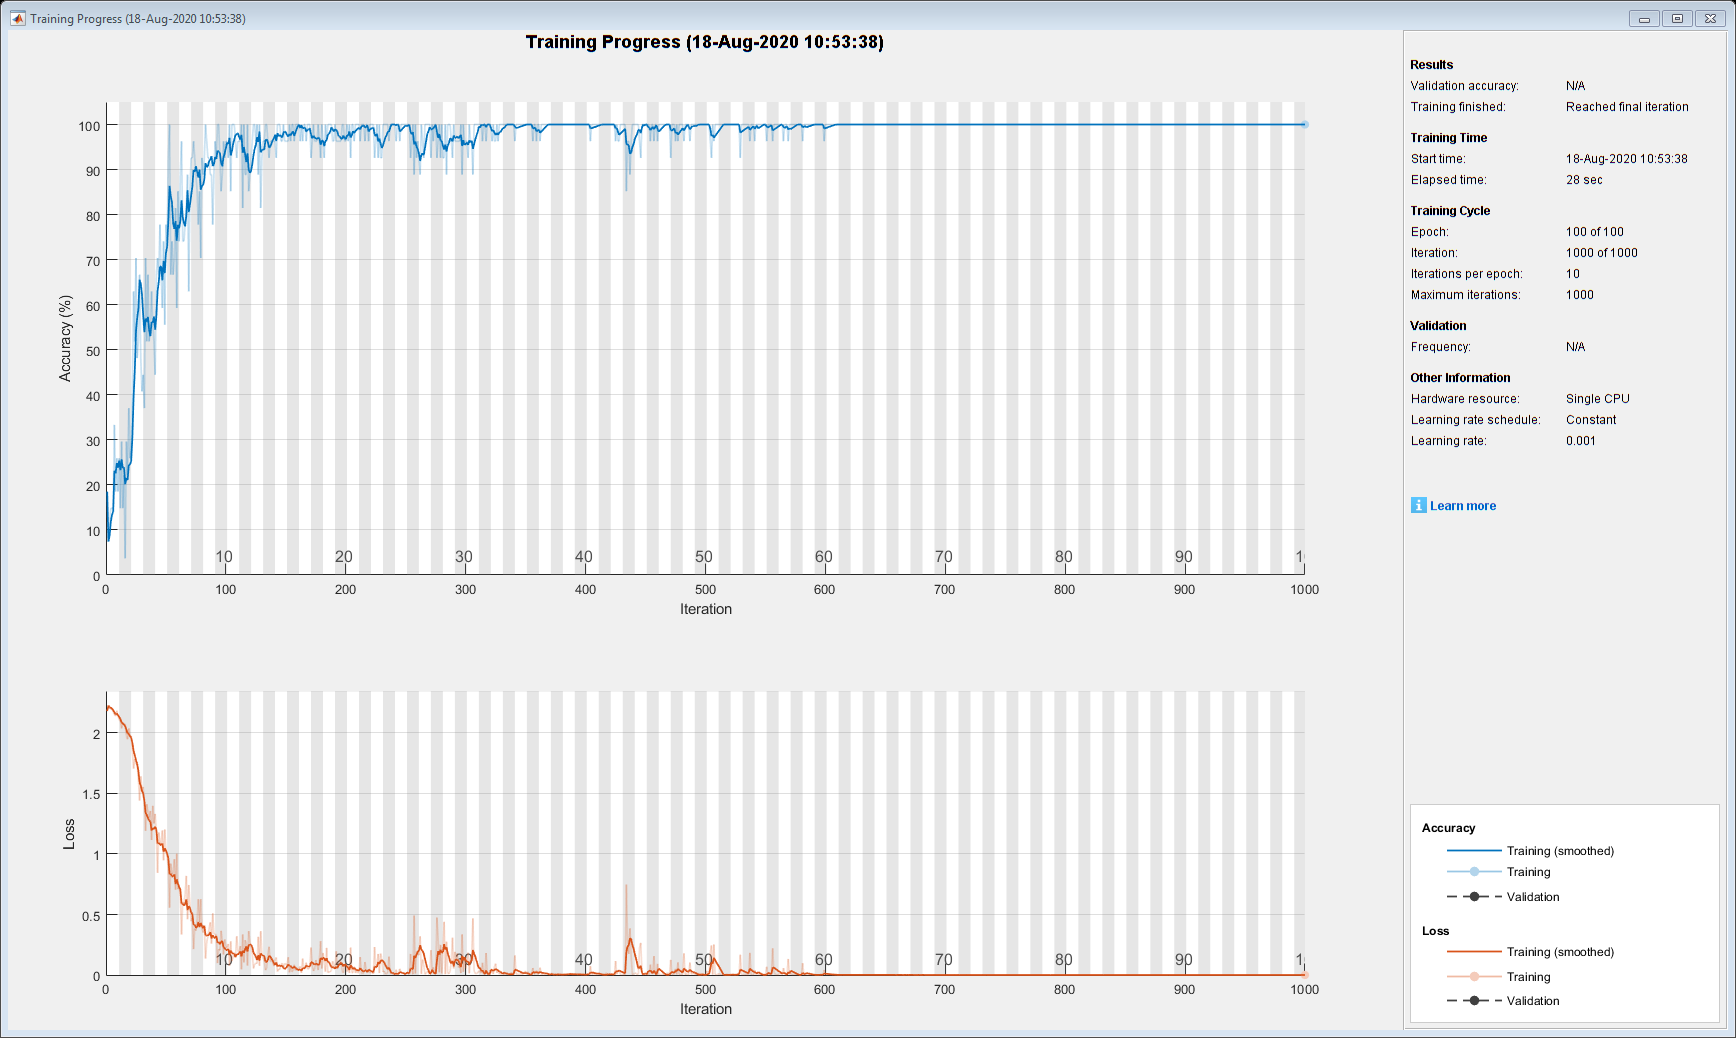

net = trainNetwork(XTrain,YTrain,layers,options);


analyzeNetwork(net)


Test Network

[XTest,YTest] = japaneseVowelsTestData;
YPred = classify(net,XTest,'MiniBatchSize',miniBatchSize);
acc = sum(YPred == YTest)./numel(YTest)

acc = 0.9486